# Mediation analysis basic walkthrough

This script is explained in more detail in the powerpoint titled Mediation_sample_data_walkthrough

% mediation_example_script1 and 2 do the same analysis.
% ...script1 is very terse, and includes the essential commands only.
% ...script2 is longer and includes more checking that files are available, etc.


## Mediation analysis: The basics

Mediation is a useful tool for connecting variables into pathways. It extends the idea of a simple association between two variables (let's call them ***x*** and ***y****)* to a pathway involving three (or more) variables.  Let's write the association ***x*** predicts ***y*** like this: **[ *****x -> y ].***  This relationship is shown graphically in the diagram below:

Suppose we hypothesize that the effect of ***x*** on ***y*** is transmitted via its influence on an intermediate variable, ***m***.  With mediation analysis, you can build a model of associations among three variables, i.e., **[ *****x *****->***** m *****->***** y *****]**. ***m*** is a mediator, a variable that explains some or all of the relationship between ***x ***and ***y***.  

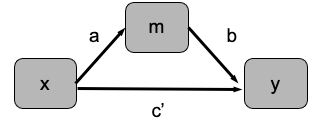

Mediation models are especially useful for developing models in which an association between two variables is transmitted via a third variable. For example, the effects of a psychological stressor (***x***) on heart rate (***y***) may be mediated by activity in brain systems responsible for threat. The stressor activates the brain, and the brain in turn controls the heart.  

In mediation analysis, ***x*** is called the *initial variable*. it will often be an experimental variable (IV) that is experimentally manipulated, but it doesn't have to be.  ***y*** is called the *outcome variable *(or *dependent variable*), and it is usually the endpoint that one is interested in explaining. m is the *mediator*, and is usually a variable that is thought to be important for transmitting the effect of ***x*** on ***y, ***or on the "causal path" from ***x ***to*** y. ***It is also possible to include multiple initial variables, multiple mediators, and other covariates in such models. The broader family that the [ *x *->* m *->* y *] model belongs to is called **path models****.**

### Brain mediators and mediation effect parametric mapping (MEPM)

Mediation is a natural fit for neuroimaging data because it lets us examine the relationships between experimental variables (e.g., task conditions), brain responses (e.g., contrast values), and outcomes (e.g., behavior or experience) in a single model. These relationships would often be tested piecemeal in standard GLM analyses. The mediation analysis allows us to identify brain regions with effect sizes for the task -> brain and brain -> outcome relationships that are jointly large enough to explain task effects on the outcome.  Other use cases include:

- In a Randomized Controlled Trial, testing whether brain responses mediate the effects of treatment assignment on clinical outcomes

- Testing whether brain activity mediates the effects of clinical status (does the person have fibromyalgia or not) on symptoms (pain or fatigue)

- Testing whether brain activity in one area (e.g., nucleus accumbens) mediates the relationship between another brain area (e.g., prefrontal cortex) and a behavior (e.g., emotion regulation success).

Mediation analyses can be done at two levels. In **single-level mediation**, there is one observation per person. Each person has a value for x, m, and y, and the mediation model tests correlations between individual differences in scores on each variable. This is the most common type of mediation analysis.  In **multi-level mediation**, we manipulate tasks and observe both brain activity and behavioral responses (e.g., ratings or performance) within-person across time (or trials in task). 

The [Multilevel Mediation and Moderation (M3) Matlab Toolbox](https://github.com/canlab/MediationToolbox) will perform both single- and multilevel mediation. The function **mediation.m** can operate on any type of input data (behavior, psychosocial measures, physiology, brain, genetics, etc.), and will run both single and multilevel mediation depending on the input data.

The toolbox also has special functions for running mediation on each voxel in a neuroimaging dataset (single or multilevel) and saving maps of mediation effects:

 Here, we'll explore single-level mediation, and we'll deal with the multi-level case in a later tutorial.  So we'll run `mediation_brain`. This function takes a series of brain images (i.e., one image per person) as one of its inputs (either x, m, or y). The other inputs are vectors, with one observation per person.   `mediation_brain `will load the images from (a) a series of 3-D .nii or .img files [one per person] or (b) a 4-D .nii file with one volume per person.  It will run mediation analysis with mulitple options (e.g., bias-corrected, accelerated bootstrap tests and robust regression are desirable) on each voxel individually, saving the path a, path b, and a*b mediation effects in image files.  

The **output** is a set of brain images with the **Path a **slopes ("effects") and P-values, **Path b** slopes and P-values, and a*b slopes and P-values.  Special functions like **mediation_brain_results** help to load these images and get, show, and make tables of results.  Scripts including **mediation_brain_results_all_script **generate a whole set of results, tables, and figures for multiple effects.  **publish_mediation_report** generates a series of results figures and tables and saves them in a date-stamped HTML report.

 For example, if we're testing whether 

 -- but most often m, if we're testing brain activity as a mediator of something else).

## About the dataset

"Wager_et_al_2008_Neuron_EmotionReg" The dataset is a series of contrast images from N = 30 participants. Each image is a contrast image for [reappraise neg vs. look neg]

These data were published in: Wager, T. D., Davidson, M. L., Hughes, B. L., Lindquist, M. A., Ochsner, K. N.. (2008). Prefrontal-subcortical pathways mediating successful emotion regulation. Neuron, 59, 1037-50.

In this study, each participant performed three tasks: 

(1) Viewing affectively neutral images (Look Neu)

(2) Viewing aversive images (Look Neg)

(3) Viewing aversive images and reappraising them to make them less aversive (Reapp Neg)

For example, when reappraising the spider image below, you might notice the egg sacs on her back and realize that this is a cute momma spider.

Negative affect reports are shown for the three conditions below.  Reappraising caused a significant drop in self-reported affect (red vs. blue bars). The  difference scores for this [Reappraise Negative - Look Negative] contrast are defined as "Reappraisal success" for a person.

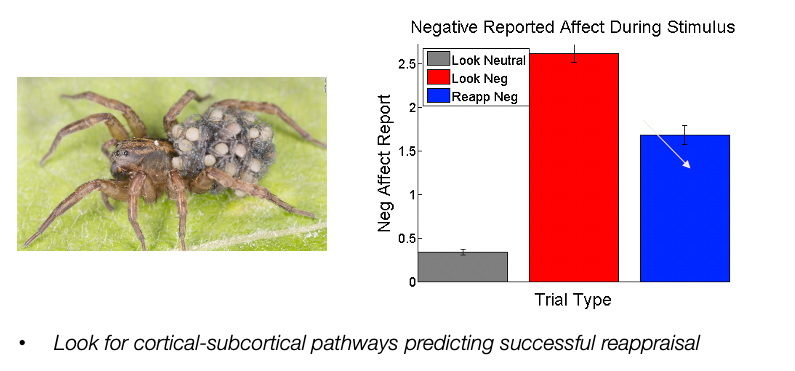

In this tutorial, we'll identify regions that mediate effects of a pre-defined lateral prefrontal (PFC) region of interest on Reappraisal Success.  We'll treat Reappraisal Success as the outcome (Y). The X values will be scores on the [Reappraise Negative - Look Negative] for each of 30 participants averaged over a right PFC region. For the mediator (M), we'll enter the name of a 4-D .nii image containing 30 [Reappraise Negative - Look Negative] images, one for each participant.  

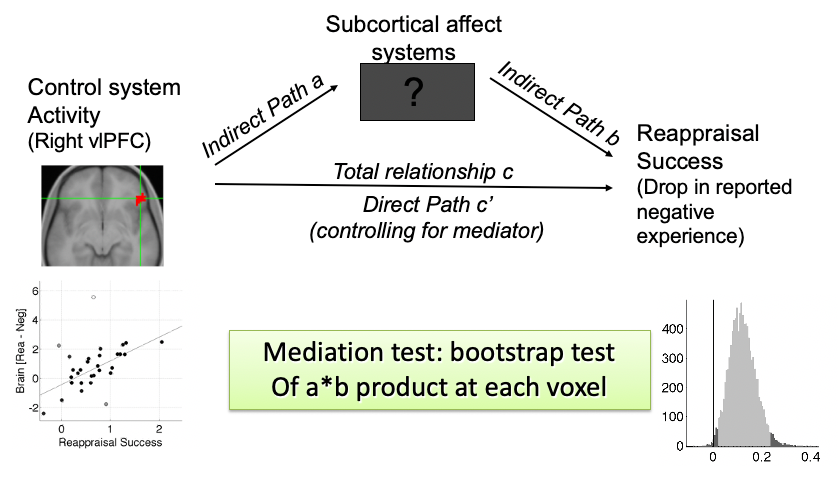

`mediation_brain `will test the PFC -> [Voxel] -> Success pathway for each voxel in the brain, saving maps of each relevant effect.

The focus of the publication was on subcortical systems, particularly nucleus accumbens and amygdala. The published analyses used robust boostrapped analyses with 10,000 samples, which take a long time to estimate. The current version of this tutorial uses more "quick and dirty" methods and so produces different results -- but it illustrates the concept.

## Step 1: Make a new analysis directory to save results, and go there

Make a new analysis directory to save results, and go there

andir = 'Test_mediation';
mkdir(andir)
cd(andir)

## Step 2: Load image data and behavioral variables

dinf = what('Wager_et_al_2008_Neuron_EmotionReg');

%imgs = filenames(fullfile(dinf.path,'con_*img'), 'char', 'absolute');
imgs = fullfile(dinf(1).path, 'Wager_2008_emo_reg_vs_look_neg_contrast_images.nii.gz');


behav_dat = importdata(fullfile(dinf(1).path,'Wager_2008_emotionreg_behavioral_data.txt'))

behav_dat = struct with fields:
          data: [30×2 double]
      textdata: {'X_RVLPFC'  'Y_Reappraisal_Success'}
    colheaders: {'X_RVLPFC'  'Y_Reappraisal_Success'}


Note: an alternative, convenient way to load the imaging (but not behavioral) data into an object is below. This allows you to explore the dataset with other CANlab tools. There are a number of other datasets and brain patterns that can be loaded this way.

## Step 3: Load and display mask

The mask determines which voxels are analyzed. The standard mask is in the CanlabCore Tools repository, so you need the folder containing it (and other CanlabCore folders) on your path.

mask = which('gray_matter_mask.img')

mask = '/Users/torwager/Documents/GitHub/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/gray_matter_mask.img'

Using default mask: /Users/torwager/Documents/GitHub/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 971812 bytes
Loading image number:     1
Elapsed time is 0.038041 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 27910  Bit rate: 14.77 bits
Grouping contiguous voxels:  17 regions
Setting up fmridisplay objects


axial montage: 41163 voxels displayed, 164384 not displayed on these slices


sagittal montage: 8079 voxels displayed, 197468 not displayed on these slices


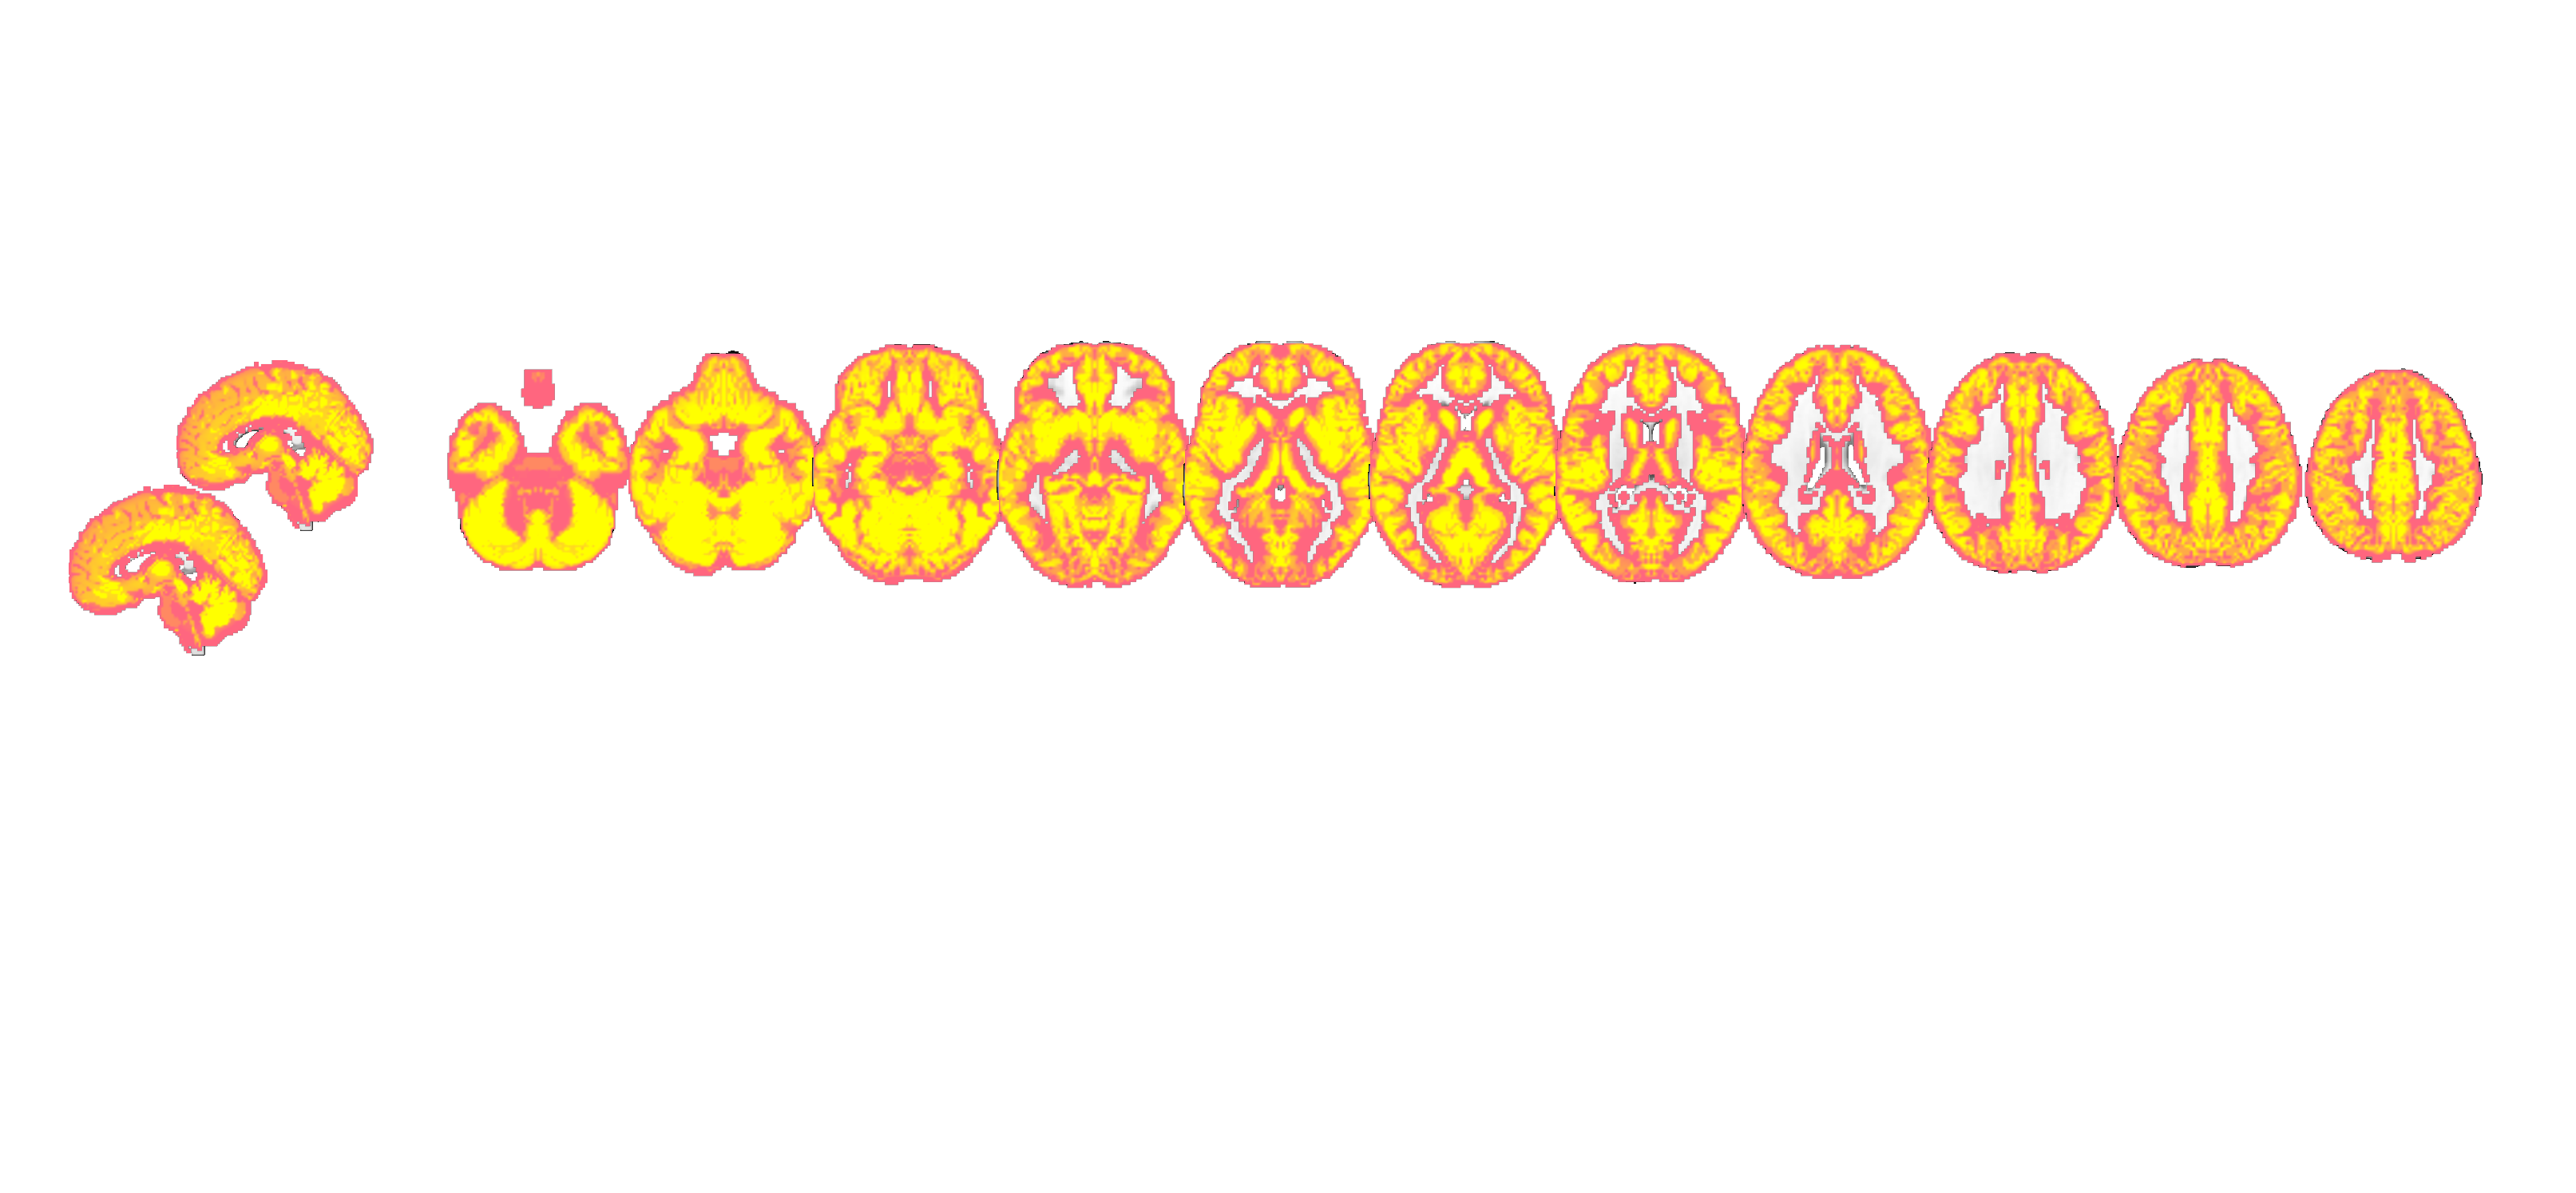

canlab_results_fmridisplay(mask, 'compact2');

## Step 4 : Run mediation

Run mediation without bootstrapping (fast) Test that things are working

Mask: /Users/torwager/Documents/GitHub/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/gray_matter_mask.img
Rank data: No

Statistics.


Slice   1 : 493 voxels in-mask
Testing 493 valid columns of 493 total in matrix - current:      1 
The mediation output below (and in the figures) is shown for
the first valid voxel in the brain. 
It is intended to give you an idea of what the 
variables and output look like so you can check      1Mediation analysis

Observations:  30, Replications:   1
Predictor (X): X:RVLPFC, Outcome (Y): Y:Reappraisal_Success: Mediator (M): M:BrainMediator

Covariates: No

Single-level analysis.
Options:
	Plots: Yes
	Bootstrap: No
	Robust: No
	Logistic(Y): No
 Done.


Mediation scatterplots:
Replications:   1
Covariates controlled for in all regressions:   0 predictors
Additional mediators controlled for in outcome predictions:   1 predictors



________________________________________

Single-level model
	a	b	c'	c	ab	
Coeff	0.21	-0.16	0.14	0.11	-0.03	
STE	0.15	0.07	0.06	0.06	0.03	
t (~N)	1.40	-2.12	2.30	1.71	-1.09	
Z	1.37	-2.03	2.18	1.66	-1.07	
p	0.1720	0.0427	0.0291	0.0974	0.2859	

________________________________________
Total time:    493Done in   3 s


Slice   2 : 715 voxels in-mask
Testing 715 valid columns of 715 total in matrix - current:      1 
The mediation output below (and in the figures) is shown for
the first valid voxel in the brain. 
It is intended to give you an idea of what the 
variables and output look like so you can check      1Mediation analysis

Observations:  30, Replications:   1
Predictor (X): X:RVLPFC, Outcome (Y): Y:Reappraisal_Success: Mediator (M): M:BrainMediator

Covariates: No

Single-level analysis.
Options:
	Plots: Yes
	Bootstrap: No
	Robust: No
	Logistic(Y): No
 Done.


Mediation scatterplots:
Replications:   1
Covariates controlled for in all regressions:   0 predictors
Additional mediators controlled for in outcome predictions:   1 predictors



________________________________________

Single-level model
	a	b	c'	c	ab	
Coeff	0.27	-0.16	0.15	0.11	-0.04	
STE	0.15	0.08	0.06	0.06	0.03	
t (~N)	1.82	-2.08	2.39	1.71	-1.28	
Z	1.75	-1.98	2.26	1.66	-1.26	
p	0.0799	0.0472	0.0240	0.0974	0.2095	

________________________________________
Total time:    715Done in   2 s


Slice   3 : 807 voxels in-mask
Testing 807 valid columns of 807 total in matrix - current:      1 
The mediation output below (and in the figures) is shown for
the first valid voxel in the brain. 
It is intended to give you an idea of what the 
variables and output look like so you can check      1Mediation analysis

Observations:  30, Replications:   1
Predictor (X): X:RVLPFC, Outcome (Y): Y:Reappraisal_Success: Mediator (M): M:BrainMediator

Covariates: No

Single-level analysis.
Options:
	Plots: Yes
	Bootstrap: No
	Robust: No
	Logistic(Y): No
 Done.


Mediation scatterplots:
Replications:   1
Covariates controlled for in all regressions:   0 predictors
Additional mediators controlled for in outcome predictions:   1 predictors



________________________________________

Single-level model
	a	b	c'	c	ab	
Coeff	0.17	-0.12	0.13	0.11	-0.02	
STE	0.14	0.08	0.06	0.06	0.03	
t (~N)	1.22	-1.47	2.03	1.71	-0.83	
Z	1.19	-1.43	1.95	1.66	-0.82	
p	0.2321	0.1540	0.0517	0.0974	0.4133	

________________________________________
Total time:    807Done in   2 s


Slice   4 : 931 voxels in-mask
Testing 931 valid columns of 931 total in matrix - current:      1 
The mediation output below (and in the figures) is shown for
the first valid voxel in the brain. 
It is intended to give you an idea of what the 
variables and output look like so you can check      1Mediation analysis

Observations:  30, Replications:   1
Predictor (X): X:RVLPFC, Outcome (Y): Y:Reappraisal_Success: Mediator (M): M:BrainMediator

Covariates: No

Single-level analysis.
Options:
	Plots: Yes
	Bootstrap: No
	Robust: No
	Logistic(Y): No
 Done.


Mediation scatterplots:
Replications:   1
Covariates controlled for in all regressions:   0 predictors
Additional mediators controlled for in outcome predictions:   1 predictors



________________________________________

Single-level model
	a	b	c'	c	ab	
Coeff	0.10	-0.01	0.11	0.11	-0.00	
STE	0.27	0.04	0.07	0.06	0.01	
t (~N)	0.37	-0.32	1.70	1.71	-0.10	
Z	0.36	-0.31	1.65	1.66	-0.10	
p	0.7165	0.7549	0.0997	0.0974	0.9179	

________________________________________
Total time:    931Done in   3 s


Slice   5 : 1076 voxels in-mask
Testing 1076 valid columns of 1076 total in matrix - current:      1 
The mediation output below (and in the figures) is shown for
the first valid voxel in the brain. 
It is intended to give you an idea of what the 
variables and output look like so you can check      1Mediation analysis

Observations:  30, Replications:   1
Predictor (X): X:RVLPFC, Outcome (Y): Y:Reappraisal_Success: Mediator (M): M:BrainMediator

Covariates: No

Single-level analysis.
Options:
	Plots: Yes
	Bootstrap: No
	Robust: No
	Logistic(Y): No
 Done.


Mediation scatterplots:
Replications:   1
Covariates controlled for in all regressions:   0 predictors
Additional mediators controlled for in outcome predictions:   1 predictors



________________________________________

Single-level model
	a	b	c'	c	ab	
Coeff	0.40	0.01	0.11	0.11	0.00	
STE	0.36	0.03	0.07	0.06	0.02	
t (~N)	1.13	0.27	1.59	1.71	0.20	
Z	1.11	0.26	1.54	1.66	0.19	
p	0.2671	0.7920	0.1228	0.0974	0.8457	

________________________________________
Total time:   1076Done in   3 s


Slice   6 : 1248 voxels in-mask
Testing 1248 valid columns of 1248 total in matrix - current:      1 
The mediation output below (and in the figures) is shown for
the first valid voxel in the brain. 
It is intended to give you an idea of what the 
variables and output look like so you can check      1Mediation analysis

Observations:  30, Replications:   1
Predictor (X): X:RVLPFC, Outcome (Y): Y:Reappraisal_Success: Mediator (M): M:BrainMediator

Covariates: No

Single-level analysis.
Options:
	Plots: Yes
	Bootstrap: No
	Robust: No
	Logistic(Y): No
 Done.


Mediation scatterplots:
Replications:   1
Covariates controlled for in all regressions:   0 predictors
Additional mediators controlled for in outcome predictions:   1 predictors



________________________________________

Single-level model
	a	b	c'	c	ab	
Coeff	0.66	0.01	0.10	0.11	0.01	
STE	0.34	0.04	0.07	0.06	0.03	
t (~N)	1.93	0.23	1.50	1.71	0.20	
Z	1.85	0.23	1.46	1.66	0.20	
p	0.0639	0.8212	0.1438	0.0974	0.8419	

________________________________________
Total time:   1248Done in   4 s


Slice   7 : 1383 voxels in-mask
Testing 1383 valid columns of 1383 total in matrix - current:      1 
The mediation output below (and in the figures) is shown for
the first valid voxel in the brain. 
It is intended to give you an idea of what the 
variables and output look like so you can check      1Mediation analysis

Observations:  30, Replications:   1
Predictor (X): X:RVLPFC, Outcome (Y): Y:Reappraisal_Success: Mediator (M): M:BrainMediator

Covariates: No

Single-level analysis.
Options:
	Plots: Yes
	Bootstrap: No
	Robust: No
	Logistic(Y): No
 Done.


Mediation scatterplots:
Replications:   1
Covariates controlled for in all regressions:   0 predictors
Additional mediators controlled for in outcome predictions:   1 predictors



________________________________________

Single-level model
	a	b	c'	c	ab	
Coeff	1.43	0.03	0.07	0.11	0.04	
STE	0.49	0.02	0.07	0.06	0.04	
t (~N)	2.91	1.16	0.95	1.71	1.02	
Z	2.70	1.13	0.94	1.66	1.00	
p	0.0069	0.2577	0.3486	0.0974	0.3152	

________________________________________
Total time:   1383Done in   6 s


Slice   8 : 1547 voxels in-mask
Testing 1546 valid columns of 1547 total in matrix - current:      1 
The mediation output below (and in the figures) is shown for
the first valid voxel in the brain. 
It is intended to give you an idea of what the 
variables and output look like so you can check      1Mediation analysis

Observations:  30, Replications:   1
Predictor (X): X:RVLPFC, Outcome (Y): Y:Reappraisal_Success: Mediator (M): M:BrainMediator

Covariates: No

Single-level analysis.
Options:
	Plots: Yes
	Bootstrap: No
	Robust: No
	Logistic(Y): No
 Done.


Mediation scatterplots:
Replications:   1
Covariates controlled for in all regressions:   0 predictors
Additional mediators controlled for in outcome predictions:   1 predictors



________________________________________

Single-level model
	a	b	c'	c	ab	
Coeff	0.90	0.02	0.09	0.11	0.02	
STE	0.34	0.04	0.07	0.06	0.04	
t (~N)	2.63	0.66	1.23	1.71	0.60	
Z	2.47	0.65	1.20	1.66	0.59	
p	0.0137	0.5177	0.2299	0.0974	0.5558	

________________________________________
Total time:   1547Done in   3 s


Slice   9 : 1614 voxels in-mask
Testing 1613 valid columns of 1614 total in matrix - current:      1 
The mediation output below (and in the figures) is shown for
the first valid voxel in the brain. 
It is intended to give you an idea of what the 
variables and output look like so you can check      1Mediation analysis

Observations:  30, Replications:   1
Predictor (X): X:RVLPFC, Outcome (Y): Y:Reappraisal_Success: Mediator (M): M:BrainMediator

Covariates: No

Single-level analysis.
Options:
	Plots: Yes
	Bootstrap: No
	Robust: No
	Logistic(Y): No
 Done.


Mediation scatterplots:
Replications:   1
Covariates controlled for in all regressions:   0 predictors
Additional mediators controlled for in outcome predictions:   1 predictors



________________________________________

Single-level model
	a	b	c'	c	ab	
Coeff	0.58	0.02	0.10	0.11	0.01	
STE	0.27	0.04	0.07	0.06	0.03	
t (~N)	2.12	0.38	1.42	1.71	0.34	
Z	2.03	0.38	1.39	1.66	0.34	
p	0.0425	0.7066	0.1656	0.0974	0.7367	

________________________________________
Total time:   1614Done in   3 s


Slice  10 : 1589 voxels in-mask
Testing 1588 valid columns of 1589 total in matrix - current:      1 
The mediation output below (and in the figures) is shown for
the first valid voxel in the brain. 
It is intended to give you an idea of what the 
variables and output look like so you can check      1Mediation analysis

Observations:  30, Replications:   1
Predictor (X): X:RVLPFC, Outcome (Y): Y:Reappraisal_Success: Mediator (M): M:BrainMediator

Covariates: No

Single-level analysis.
Options:
	Plots: Yes
	Bootstrap: No
	Robust: No
	Logistic(Y): No
 Done.


Mediation scatterplots:
Replications:   1
Covariates controlled for in all regressions:   0 predictors
Additional mediators controlled for in outcome predictions:   1 predictors



________________________________________

Single-level model
	a	b	c'	c	ab	
Coeff	0.71	0.03	0.09	0.11	0.02	
STE	0.28	0.04	0.07	0.06	0.03	
t (~N)	2.55	0.58	1.27	1.71	0.53	
Z	2.41	0.58	1.24	1.66	0.53	
p	0.0162	0.5635	0.2145	0.0974	0.5986	

________________________________________
Total time:   1589Done in   3 s


Slice  11 : 1515 voxels in-mask
Testing 1515 valid columns of 1515 total in matrix - current:      1 
The mediation output below (and in the figures) is shown for
the first valid voxel in the brain. 
It is intended to give you an idea of what the 
variables and output look like so you can check      1Mediation analysis

Observations:  30, Replications:   1
Predictor (X): X:RVLPFC, Outcome (Y): Y:Reappraisal_Success: Mediator (M): M:BrainMediator

Covariates: No

Single-level analysis.
Options:
	Plots: Yes
	Bootstrap: No
	Robust: No
	Logistic(Y): No
 Done.


Mediation scatterplots:
Replications:   1
Covariates controlled for in all regressions:   0 predictors
Additional mediators controlled for in outcome predictions:   1 predictors



________________________________________

Single-level model
	a	b	c'	c	ab	
Coeff	0.35	-0.04	0.12	0.11	-0.01	
STE	0.14	0.09	0.07	0.06	0.03	
t (~N)	2.43	-0.47	1.73	1.71	-0.43	
Z	2.30	-0.46	1.67	1.66	-0.42	
p	0.0213	0.6426	0.0946	0.0974	0.6725	

________________________________________
Total time:   1515Done in   3 s


Slice  12 : 1461 voxels in-mask
Testing 1461 valid columns of 1461 total in matrix - current:      1 
The mediation output below (and in the figures) is shown for
the first valid voxel in the brain. 
It is intended to give you an idea of what the 
variables and output look like so you can check      1Mediation analysis

Observations:  30, Replications:   1
Predictor (X): X:RVLPFC, Outcome (Y): Y:Reappraisal_Success: Mediator (M): M:BrainMediator

Covariates: No

Single-level analysis.
Options:
	Plots: Yes
	Bootstrap: No
	Robust: No
	Logistic(Y): No
 Done.


Mediation scatterplots:
Replications:   1
Covariates controlled for in all regressions:   0 predictors
Additional mediators controlled for in outcome predictions:   1 predictors



________________________________________

Single-level model
	a	b	c'	c	ab	
Coeff	0.27	-0.01	0.11	0.11	-0.00	
STE	0.13	0.09	0.07	0.06	0.03	
t (~N)	2.01	-0.08	1.60	1.71	-0.07	
Z	1.93	-0.08	1.55	1.66	-0.07	
p	0.0535	0.9356	0.1205	0.0974	0.9424	

________________________________________
Total time:   1461Done in   3 s


Slice  13 : 1451 voxels in-mask
Testing 1451 valid columns of 1451 total in matrix - current:      1 
The mediation output below (and in the figures) is shown for
the first valid voxel in the brain. 
It is intended to give you an idea of what the 
variables and output look like so you can check      1Mediation analysis

Observations:  30, Replications:   1
Predictor (X): X:RVLPFC, Outcome (Y): Y:Reappraisal_Success: Mediator (M): M:BrainMediator

Covariates: No

Single-level analysis.
Options:
	Plots: Yes
	Bootstrap: No
	Robust: No
	Logistic(Y): No
 Done.


Mediation scatterplots:
Replications:   1
Covariates controlled for in all regressions:   0 predictors
Additional mediators controlled for in outcome predictions:   1 predictors



________________________________________

Single-level model
	a	b	c'	c	ab	
Coeff	0.16	0.02	0.11	0.11	0.00	
STE	0.14	0.09	0.07	0.06	0.02	
t (~N)	1.17	0.20	1.60	1.71	0.15	
Z	1.14	0.20	1.55	1.66	0.15	
p	0.2524	0.8397	0.1209	0.0974	0.8789	

________________________________________
Total time:   1451Done in   3 s


Slice  14 : 1434 voxels in-mask
Testing 1434 valid columns of 1434 total in matrix - current:      1 
The mediation output below (and in the figures) is shown for
the first valid voxel in the brain. 
It is intended to give you an idea of what the 
variables and output look like so you can check      1Mediation analysis

Observations:  30, Replications:   1
Predictor (X): X:RVLPFC, Outcome (Y): Y:Reappraisal_Success: Mediator (M): M:BrainMediator

Covariates: No

Single-level analysis.
Options:
	Plots: Yes
	Bootstrap: No
	Robust: No
	Logistic(Y): No
 Done.


Mediation scatterplots:
Replications:   1
Covariates controlled for in all regressions:   0 predictors
Additional mediators controlled for in outcome predictions:   1 predictors



________________________________________

Single-level model
	a	b	c'	c	ab	
Coeff	1.04	0.04	0.07	0.11	0.04	
STE	0.48	0.02	0.07	0.06	0.03	
t (~N)	2.18	1.47	1.06	1.71	1.14	
Z	2.08	1.43	1.04	1.66	1.12	
p	0.0379	0.1527	0.2992	0.0974	0.2646	

________________________________________
Total time:   1434Done in   3 s


Slice  15 : 1337 voxels in-mask
Testing 1337 valid columns of 1337 total in matrix - current:      1 
The mediation output below (and in the figures) is shown for
the first valid voxel in the brain. 
It is intended to give you an idea of what the 
variables and output look like so you can check      1Mediation analysis

Observations:  30, Replications:   1
Predictor (X): X:RVLPFC, Outcome (Y): Y:Reappraisal_Success: Mediator (M): M:BrainMediator

Covariates: No

Single-level analysis.
Options:
	Plots: Yes
	Bootstrap: No
	Robust: No
	Logistic(Y): No
 Done.


Mediation scatterplots:
Replications:   1
Covariates controlled for in all regressions:   0 predictors
Additional mediators controlled for in outcome predictions:   1 predictors



________________________________________

Single-level model
	a	b	c'	c	ab	
Coeff	0.25	0.03	0.10	0.11	0.01	
STE	0.14	0.08	0.07	0.06	0.03	
t (~N)	1.74	0.41	1.48	1.71	0.35	
Z	1.68	0.40	1.43	1.66	0.34	
p	0.0926	0.6860	0.1513	0.0974	0.7312	

________________________________________
Total time:   1337Done in   3 s


Slice  16 : 1250 voxels in-mask
Testing 1250 valid columns of 1250 total in matrix - current:      1 
The mediation output below (and in the figures) is shown for
the first valid voxel in the brain. 
It is intended to give you an idea of what the 
variables and output look like so you can check      1Mediation analysis

Observations:  30, Replications:   1
Predictor (X): X:RVLPFC, Outcome (Y): Y:Reappraisal_Success: Mediator (M): M:BrainMediator

Covariates: No

Single-level analysis.
Options:
	Plots: Yes
	Bootstrap: No
	Robust: No
	Logistic(Y): No
 Done.


Mediation scatterplots:
Replications:   1
Covariates controlled for in all regressions:   0 predictors
Additional mediators controlled for in outcome predictions:   1 predictors



________________________________________

Single-level model
	a	b	c'	c	ab	
Coeff	0.18	0.04	0.10	0.11	0.01	
STE	0.14	0.09	0.07	0.06	0.02	
t (~N)	1.32	0.39	1.54	1.71	0.30	
Z	1.29	0.38	1.50	1.66	0.30	
p	0.1974	0.7010	0.1341	0.0974	0.7656	

________________________________________
Total time:   1250Done in   3 s


Slice  17 : 1165 voxels in-mask
Testing 1165 valid columns of 1165 total in matrix - current:      1 
The mediation output below (and in the figures) is shown for
the first valid voxel in the brain. 
It is intended to give you an idea of what the 
variables and output look like so you can check      1Mediation analysis

Observations:  30, Replications:   1
Predictor (X): X:RVLPFC, Outcome (Y): Y:Reappraisal_Success: Mediator (M): M:BrainMediator

Covariates: No

Single-level analysis.
Options:
	Plots: Yes
	Bootstrap: No
	Robust: No
	Logistic(Y): No
 Done.


Mediation scatterplots:
Replications:   1
Covariates controlled for in all regressions:   0 predictors
Additional mediators controlled for in outcome predictions:   1 predictors



________________________________________

Single-level model
	a	b	c'	c	ab	
Coeff	0.69	0.01	0.10	0.11	0.01	
STE	0.34	0.04	0.07	0.06	0.03	
t (~N)	2.02	0.29	1.47	1.71	0.26	
Z	1.94	0.29	1.43	1.66	0.26	
p	0.0525	0.7736	0.1527	0.0974	0.7981	

________________________________________
Total time:   1165Done in   2 s


Slice  18 : 1073 voxels in-mask
Testing 1073 valid columns of 1073 total in matrix - current:      1 
The mediation output below (and in the figures) is shown for
the first valid voxel in the brain. 
It is intended to give you an idea of what the 
variables and output look like so you can check      1Mediation analysis

Observations:  30, Replications:   1
Predictor (X): X:RVLPFC, Outcome (Y): Y:Reappraisal_Success: Mediator (M): M:BrainMediator

Covariates: No

Single-level analysis.
Options:
	Plots: Yes
	Bootstrap: No
	Robust: No
	Logistic(Y): No
 Done.


Mediation scatterplots:
Replications:   1
Covariates controlled for in all regressions:   0 predictors
Additional mediators controlled for in outcome predictions:   1 predictors



________________________________________

Single-level model
	a	b	c'	c	ab	
Coeff	0.36	0.15	0.06	0.11	0.05	
STE	0.17	0.07	0.06	0.06	0.04	
t (~N)	2.14	2.22	0.87	1.71	1.46	
Z	2.04	2.11	0.85	1.66	1.42	
p	0.0410	0.0351	0.3943	0.0974	0.1545	

________________________________________
Total time:   1073Done in   3 s


Slice  19 : 1097 voxels in-mask
Testing 1097 valid columns of 1097 total in matrix - current:      1 
The mediation output below (and in the figures) is shown for
the first valid voxel in the brain. 
It is intended to give you an idea of what the 
variables and output look like so you can check      1Mediation analysis

Observations:  30, Replications:   1
Predictor (X): X:RVLPFC, Outcome (Y): Y:Reappraisal_Success: Mediator (M): M:BrainMediator

Covariates: No

Single-level analysis.
Options:
	Plots: Yes
	Bootstrap: No
	Robust: No
	Logistic(Y): No
 Done.


Mediation scatterplots:
Replications:   1
Covariates controlled for in all regressions:   0 predictors
Additional mediators controlled for in outcome predictions:   1 predictors



________________________________________

Single-level model
	a	b	c'	c	ab	
Coeff	0.38	0.13	0.06	0.11	0.05	
STE	0.19	0.06	0.06	0.06	0.04	
t (~N)	2.03	2.06	0.95	1.71	1.37	
Z	1.94	1.97	0.94	1.66	1.33	
p	0.0520	0.0488	0.3489	0.0974	0.1830	

________________________________________
Total time:   1097Done in   3 s


Slice  20 : 1122 voxels in-mask
Testing 1122 valid columns of 1122 total in matrix - current:      1 
The mediation output below (and in the figures) is shown for
the first valid voxel in the brain. 
It is intended to give you an idea of what the 
variables and output look like so you can check      1Mediation analysis

Observations:  30, Replications:   1
Predictor (X): X:RVLPFC, Outcome (Y): Y:Reappraisal_Success: Mediator (M): M:BrainMediator

Covariates: No

Single-level analysis.
Options:
	Plots: Yes
	Bootstrap: No
	Robust: No
	Logistic(Y): No
 Done.


Mediation scatterplots:
Replications:   1
Covariates controlled for in all regressions:   0 predictors
Additional mediators controlled for in outcome predictions:   1 predictors



________________________________________

Single-level model
	a	b	c'	c	ab	
Coeff	0.32	0.13	0.07	0.11	0.04	
STE	0.18	0.06	0.06	0.06	0.03	
t (~N)	1.73	2.02	1.09	1.71	1.23	
Z	1.67	1.94	1.07	1.66	1.20	
p	0.0951	0.0526	0.2856	0.0974	0.2292	

________________________________________
Total time:   1122Done in   3 s


Slice  21 : 1091 voxels in-mask
Testing 1091 valid columns of 1091 total in matrix - current:      1 
The mediation output below (and in the figures) is shown for
the first valid voxel in the brain. 
It is intended to give you an idea of what the 
variables and output look like so you can check      1Mediation analysis

Observations:  30, Replications:   1
Predictor (X): X:RVLPFC, Outcome (Y): Y:Reappraisal_Success: Mediator (M): M:BrainMediator

Covariates: No

Single-level analysis.
Options:
	Plots: Yes
	Bootstrap: No
	Robust: No
	Logistic(Y): No
 Done.


Mediation scatterplots:
Replications:   1
Covariates controlled for in all regressions:   0 predictors
Additional mediators controlled for in outcome predictions:   1 predictors



________________________________________

Single-level model
	a	b	c'	c	ab	
Coeff	0.53	0.11	0.05	0.11	0.06	
STE	0.21	0.05	0.07	0.06	0.04	
t (~N)	2.50	2.09	0.75	1.71	1.53	
Z	2.36	2.00	0.74	1.66	1.49	
p	0.0185	0.0456	0.4610	0.0974	0.1366	

________________________________________
Total time:   1091Done in   3 s


Slice  22 : 1060 voxels in-mask
Testing 1060 valid columns of 1060 total in matrix - current:      1 
The mediation output below (and in the figures) is shown for
the first valid voxel in the brain. 
It is intended to give you an idea of what the 
variables and output look like so you can check      1Mediation analysis

Observations:  30, Replications:   1
Predictor (X): X:RVLPFC, Outcome (Y): Y:Reappraisal_Success: Mediator (M): M:BrainMediator

Covariates: No

Single-level analysis.
Options:
	Plots: Yes
	Bootstrap: No
	Robust: No
	Logistic(Y): No
 Done.


Mediation scatterplots:
Replications:   1
Covariates controlled for in all regressions:   0 predictors
Additional mediators controlled for in outcome predictions:   1 predictors



________________________________________

Single-level model
	a	b	c'	c	ab	
Coeff	0.49	0.08	0.07	0.11	0.04	
STE	0.25	0.05	0.07	0.06	0.03	
t (~N)	2.00	1.74	1.04	1.71	1.23	
Z	1.92	1.68	1.02	1.66	1.20	
p	0.0544	0.0936	0.3057	0.0974	0.2297	

________________________________________
Total time:   1060Done in   2 s


Slice  23 : 981 voxels in-mask
Testing 981 valid columns of 981 total in matrix - current:      1 
The mediation output below (and in the figures) is shown for
the first valid voxel in the brain. 
It is intended to give you an idea of what the 
variables and output look like so you can check      1Mediation analysis

Observations:  30, Replications:   1
Predictor (X): X:RVLPFC, Outcome (Y): Y:Reappraisal_Success: Mediator (M): M:BrainMediator

Covariates: No

Single-level analysis.
Options:
	Plots: Yes
	Bootstrap: No
	Robust: No
	Logistic(Y): No
 Done.


Mediation scatterplots:
Replications:   1
Covariates controlled for in all regressions:   0 predictors
Additional mediators controlled for in outcome predictions:   1 predictors



________________________________________

Single-level model
	a	b	c'	c	ab	
Coeff	0.28	0.03	0.10	0.11	0.01	
STE	0.30	0.04	0.07	0.06	0.02	
t (~N)	0.95	0.61	1.56	1.71	0.39	
Z	0.93	0.61	1.51	1.66	0.38	
p	0.3517	0.5438	0.1302	0.0974	0.7026	

________________________________________
Total time:    981Done in   2 s


Slice  24 : 929 voxels in-mask
Testing 929 valid columns of 929 total in matrix - current:      1 
The mediation output below (and in the figures) is shown for
the first valid voxel in the brain. 
It is intended to give you an idea of what the 
variables and output look like so you can check      1Mediation analysis

Observations:  30, Replications:   1
Predictor (X): X:RVLPFC, Outcome (Y): Y:Reappraisal_Success: Mediator (M): M:BrainMediator

Covariates: No

Single-level analysis.
Options:
	Plots: Yes
	Bootstrap: No
	Robust: No
	Logistic(Y): No
 Done.


Mediation scatterplots:
Replications:   1
Covariates controlled for in all regressions:   0 predictors
Additional mediators controlled for in outcome predictions:   1 predictors



________________________________________

Single-level model
	a	b	c'	c	ab	
Coeff	0.38	0.04	0.09	0.11	0.02	
STE	0.32	0.04	0.07	0.06	0.02	
t (~N)	1.20	1.06	1.44	1.71	0.67	
Z	1.17	1.04	1.40	1.66	0.67	
p	0.2411	0.2970	0.1609	0.0974	0.5059	

________________________________________
Total time:    929Done in   3 s


Slice  25 : 828 voxels in-mask
Testing 828 valid columns of 828 total in matrix - current:      1 
The mediation output below (and in the figures) is shown for
the first valid voxel in the brain. 
It is intended to give you an idea of what the 
variables and output look like so you can check      1Mediation analysis

Observations:  30, Replications:   1
Predictor (X): X:RVLPFC, Outcome (Y): Y:Reappraisal_Success: Mediator (M): M:BrainMediator

Covariates: No

Single-level analysis.
Options:
	Plots: Yes
	Bootstrap: No
	Robust: No
	Logistic(Y): No
 Done.


Mediation scatterplots:
Replications:   1
Covariates controlled for in all regressions:   0 predictors
Additional mediators controlled for in outcome predictions:   1 predictors



________________________________________

Single-level model
	a	b	c'	c	ab	
Coeff	0.50	0.07	0.08	0.11	0.03	
STE	0.24	0.05	0.07	0.06	0.03	
t (~N)	2.06	1.37	1.13	1.71	1.05	
Z	1.97	1.33	1.10	1.66	1.03	
p	0.0489	0.1828	0.2696	0.0974	0.3007	

________________________________________
Total time:    828Done in   3 s


Slice  26 : 661 voxels in-mask
Testing 661 valid columns of 661 total in matrix - current:      1 
The mediation output below (and in the figures) is shown for
the first valid voxel in the brain. 
It is intended to give you an idea of what the 
variables and output look like so you can check      1Mediation analysis

Observations:  30, Replications:   1
Predictor (X): X:RVLPFC, Outcome (Y): Y:Reappraisal_Success: Mediator (M): M:BrainMediator

Covariates: No

Single-level analysis.
Options:
	Plots: Yes
	Bootstrap: No
	Robust: No
	Logistic(Y): No
 Done.


Mediation scatterplots:
Replications:   1
Covariates controlled for in all regressions:   0 predictors
Additional mediators controlled for in outcome predictions:   1 predictors



________________________________________

Single-level model
	a	b	c'	c	ab	
Coeff	0.57	0.06	0.08	0.11	0.03	
STE	0.19	0.06	0.07	0.06	0.04	
t (~N)	2.92	0.92	1.05	1.71	0.84	
Z	2.71	0.91	1.03	1.66	0.82	
p	0.0067	0.3648	0.3028	0.0974	0.4106	

________________________________________
Total time:    661Done in   3 s


Slice  27 : 521 voxels in-mask
Testing 521 valid columns of 521 total in matrix - current:      1 
The mediation output below (and in the figures) is shown for
the first valid voxel in the brain. 
It is intended to give you an idea of what the 
variables and output look like so you can check      1Mediation analysis

Observations:  30, Replications:   1
Predictor (X): X:RVLPFC, Outcome (Y): Y:Reappraisal_Success: Mediator (M): M:BrainMediator

Covariates: No

Single-level analysis.
Options:
	Plots: Yes
	Bootstrap: No
	Robust: No
	Logistic(Y): No
 Done.


Mediation scatterplots:
Replications:   1
Covariates controlled for in all regressions:   0 predictors
Additional mediators controlled for in outcome predictions:   1 predictors



________________________________________

Single-level model
	a	b	c'	c	ab	
Coeff	0.41	0.08	0.08	0.11	0.03	
STE	0.21	0.06	0.07	0.06	0.03	
t (~N)	1.98	1.42	1.13	1.71	1.07	
Z	1.90	1.39	1.11	1.66	1.05	
p	0.0570	0.1659	0.2664	0.0974	0.2940	

________________________________________
Total time:    521Done in   2 s


Slice  28 : 392 voxels in-mask
Testing 392 valid columns of 392 total in matrix - current:      1 
The mediation output below (and in the figures) is shown for
the first valid voxel in the brain. 
It is intended to give you an idea of what the 
variables and output look like so you can check      1Mediation analysis

Observations:  30, Replications:   1
Predictor (X): X:RVLPFC, Outcome (Y): Y:Reappraisal_Success: Mediator (M): M:BrainMediator

Covariates: No

Single-level analysis.
Options:
	Plots: Yes
	Bootstrap: No
	Robust: No
	Logistic(Y): No
 Done.


Mediation scatterplots:
Replications:   1
Covariates controlled for in all regressions:   0 predictors
Additional mediators controlled for in outcome predictions:   1 predictors



________________________________________

Single-level model
	a	b	c'	c	ab	
Coeff	0.16	0.07	0.10	0.11	0.01	
STE	0.15	0.08	0.07	0.06	0.02	
t (~N)	1.05	0.80	1.51	1.71	0.51	
Z	1.03	0.79	1.47	1.66	0.50	
p	0.3039	0.4306	0.1412	0.0974	0.6167	

________________________________________
Total time:    392Done in   2 s


Slice  29 : 258 voxels in-mask
Testing 258 valid columns of 258 total in matrix - current:      1 
The mediation output below (and in the figures) is shown for
the first valid voxel in the brain. 
It is intended to give you an idea of what the 
variables and output look like so you can check      1Mediation analysis

Observations:  30, Replications:   1
Predictor (X): X:RVLPFC, Outcome (Y): Y:Reappraisal_Success: Mediator (M): M:BrainMediator

Covariates: No

Single-level analysis.
Options:
	Plots: Yes
	Bootstrap: No
	Robust: No
	Logistic(Y): No
 Done.


Mediation scatterplots:
Replications:   1
Covariates controlled for in all regressions:   0 predictors
Additional mediators controlled for in outcome predictions:   1 predictors



________________________________________

Single-level model
	a	b	c'	c	ab	
Coeff	0.50	0.10	0.06	0.11	0.05	
STE	0.17	0.07	0.07	0.06	0.04	
t (~N)	2.93	1.41	0.84	1.71	1.22	
Z	2.72	1.38	0.83	1.66	1.19	
p	0.0065	0.1685	0.4082	0.0974	0.2337	

________________________________________
Total time:    258Done in   2 s


Slice  30 :  52 voxels in-mask
Testing 52 valid columns of 52 total in matrix - current:      1 
The mediation output below (and in the figures) is shown for
the first valid voxel in the brain. 
It is intended to give you an idea of what the 
variables and output look like so you can check      1Mediation analysis

Observations:  30, Replications:   1
Predictor (X): X:RVLPFC, Outcome (Y): Y:Reappraisal_Success: Mediator (M): M:BrainMediator

Covariates: No

Single-level analysis.
Options:
	Plots: Yes
	Bootstrap: No
	Robust: No
	Logistic(Y): No
 Done.


Mediation scatterplots:
Replications:   1
Covariates controlled for in all regressions:   0 predictors
Additional mediators controlled for in outcome predictions:   1 predictors


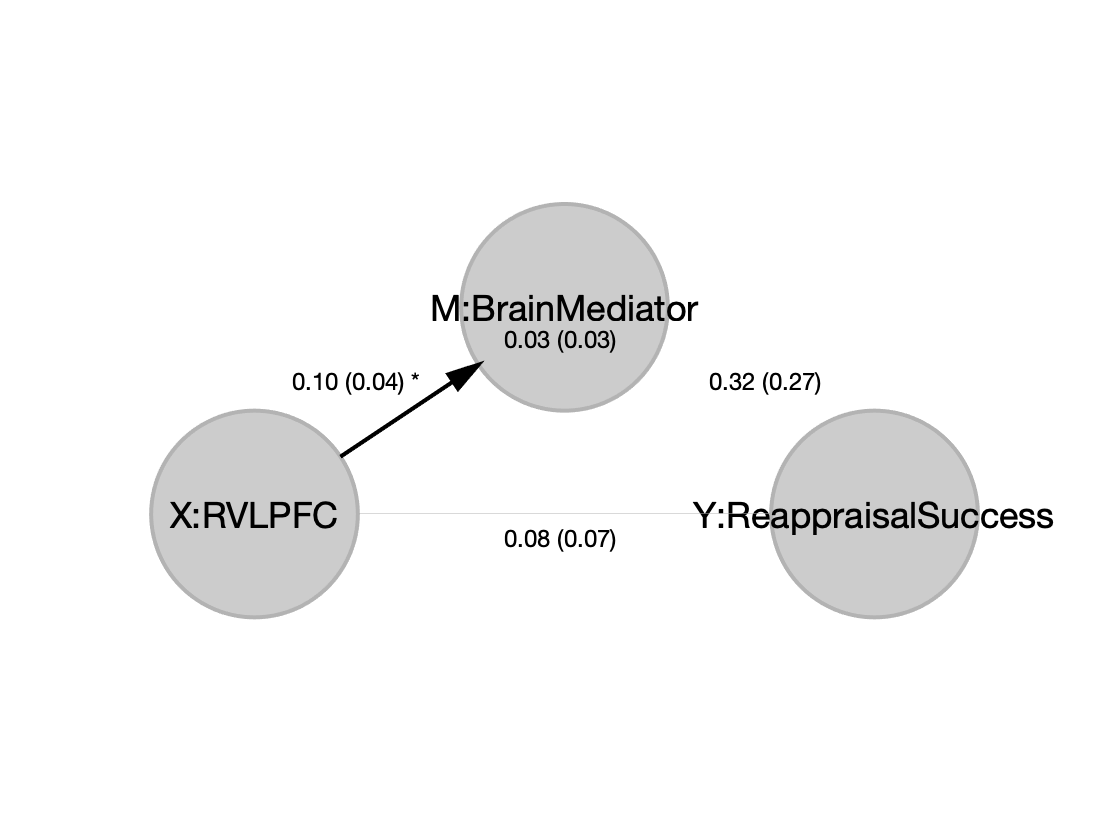

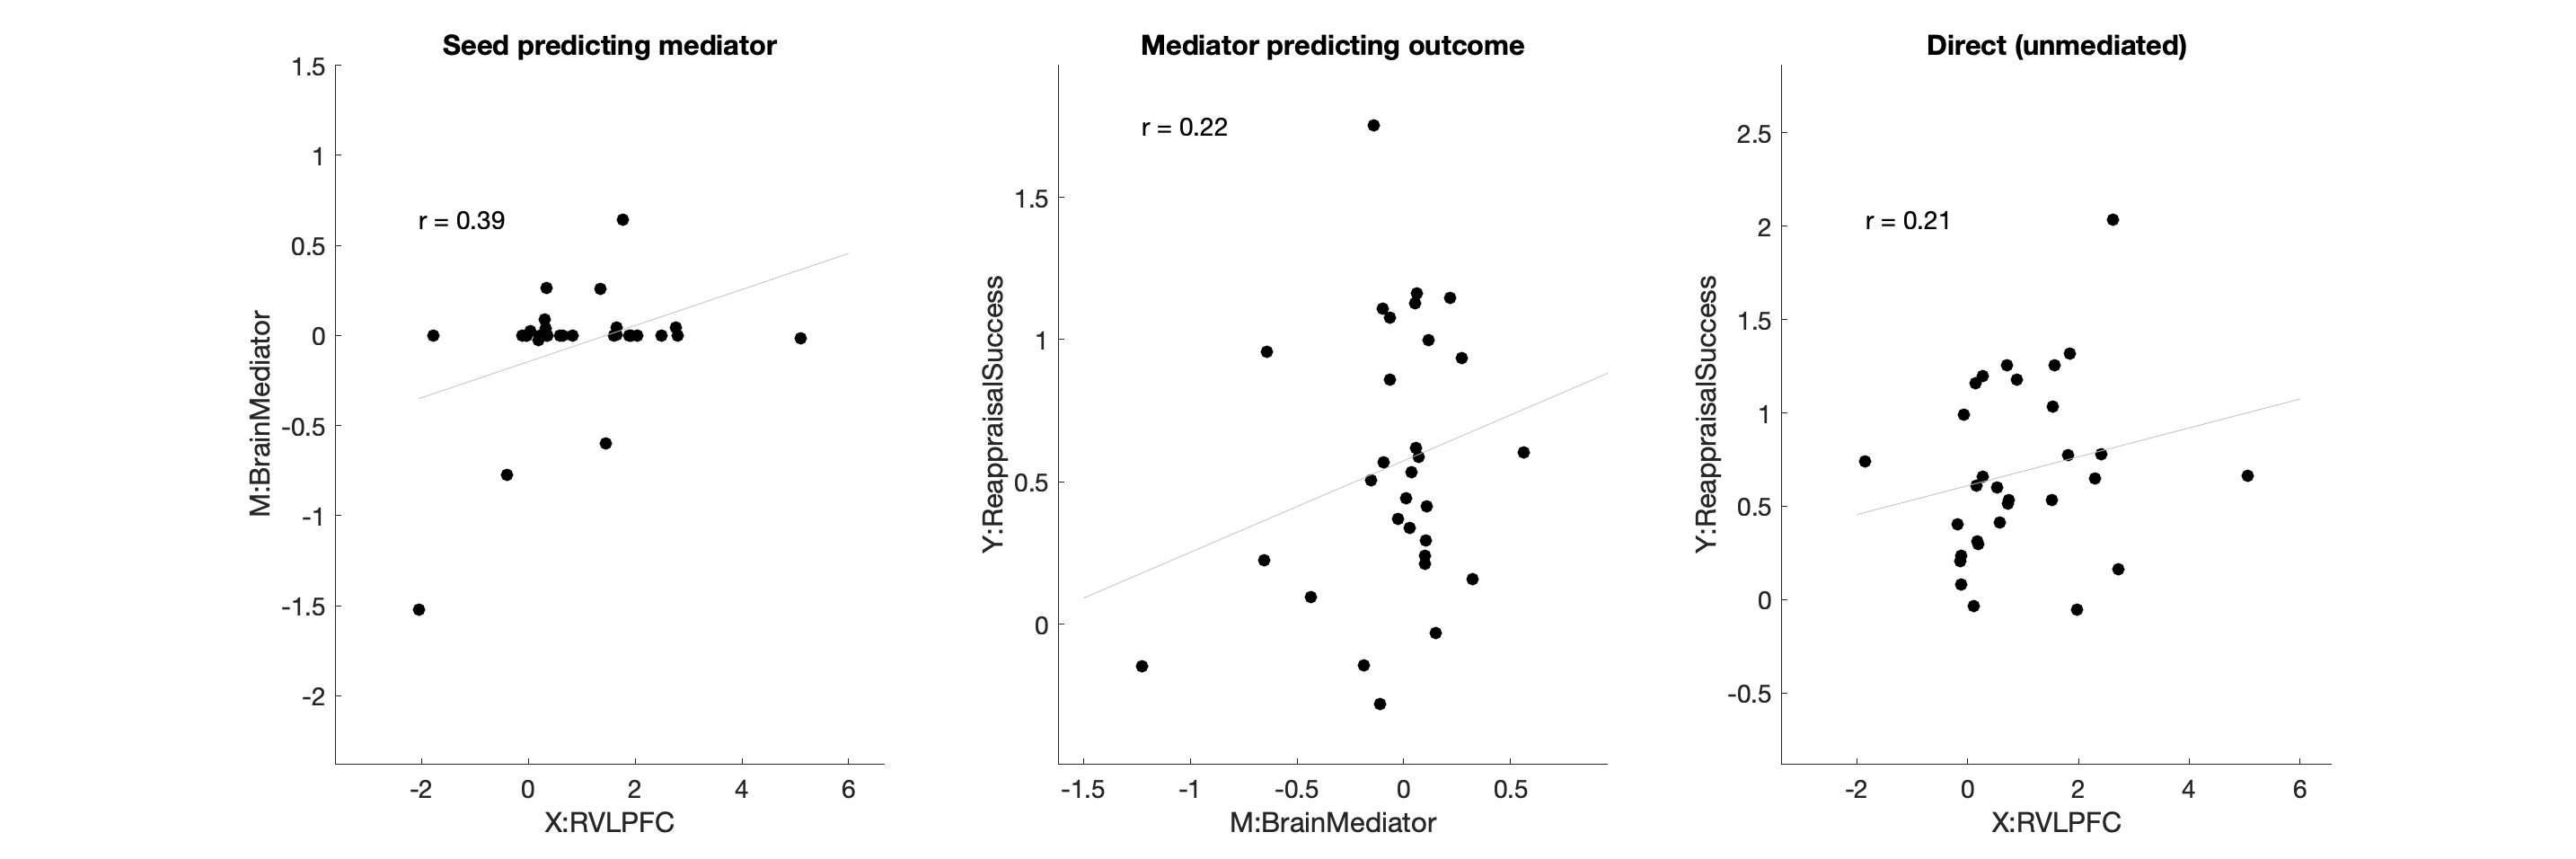


________________________________________

Single-level model
	a	b	c'	c	ab	
Coeff	0.10	0.32	0.08	0.11	0.03	
STE	0.04	0.27	0.07	0.06	0.03	
t (~N)	2.24	1.20	1.12	1.71	0.98	
Z	2.13	1.17	1.10	1.66	0.97	
p	0.0329	0.2404	0.2714	0.0974	0.3336	

________________________________________
Total time:     52Do

x=behav_dat.data(:,1);
y=behav_dat.data(:,2);
names = {'X:RVLPFC' 'Y:Reappraisal_Success' 'M:BrainMediator'};

% This is what you would run:
results = mediation_brain(x,y,imgs,'names',names,'mask', mask);

### Try it with bootstrapping (optional)

Make yourself a cup of tea while the results are compiled as this is going to take a while.

Pre-compiled results are also available in:

'mediation_Example_Data_Wager2008_Msearch_R_XisRIFGstim_norobust'

results = mediation_brain(x,y,imgs,'names',names,'mask', mask,'boot','pvals',5, 'bootsamples', 10000);

## Step 5: Get and save results figures, tables, and report

First, change to the mediation analysis directory, if you're not there already. Then, run one of several batch results functions.

The most complete way to create and publish a time- and date-stamped HTML report with figures and tables is to run "publish_mediation_report.m" 

publish_mediation_report;

Another option is to use this batch script to create figures and tables, and save .mat files with results: